# Neural Networks Part 1

## What are neural networks?

**Neural networks** are a set of algorithms that were inspired by neural circuits in the brain, and have exploded in popularity due to advances in computing technology. The central idea of neural networks is to take linear combinations of inputs as new features, then model the output as a nonlinear function of those features. We'll work on building our own neural network and perform classification on a breast cancer dataset.

### Modern applications of neural networks in "real-world" problems

Neural networks have been applied to several real-world problems, from[ determining medical diagnoses by classifying images](https://towardsdatascience.com/medical-diagnosis-with-a-convolutional-neural-network-ab0b6b455a20) to [training a self driving car](https://towardsdatascience.com/deep-learning-for-self-driving-cars-7f198ef4cfa2) to [biomedical text mining for extracting relevant patient information](https://medium.com/@Petuum/applying-neural-networks-to-biomedical-text-mining-fe655270c12). This is because they can:

- Learn using non-linear and complex relationships

- Can generalize really well on unseen data

- Are flexible in the data that is imputed (non-normal distribution, non-constant variance, etc)

### The components and notation of a neural network

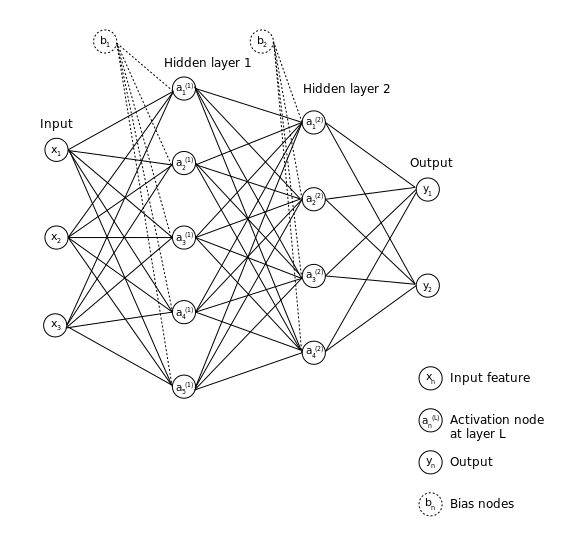

There are [several flavors of neural network architectures](https://medium.com/cracking-the-data-science-interview/a-gentle-introduction-to-neural-networks-for-machine-learning-d5f3f8987786), each one having their own advantages and disadvantages for solving different problems. The diagram above illustrates a **feed-forward neural network**, where information flows through from the input to the output, and no information feeds back into itself. This is a rather simple neural network that works for several real-word applications.

**Each component of the feed-forward neural network is described below:**

Input layer: the data ($X_{\textrm{train}}$) we are training the neural network on, where each $n^{\textrm{th}}$ column or feature vector represents a node in the network digram. The diagram above shows 3 features in the input layer.

Hidden layer(s): where the features are transformed into new data representations via linear and non-linear transformations

- Each **activation node** ($a_n$) represents our newly determined complex feature vector. A single hidden layer can consist of several activation nodes. The number of nodes and hidden layers affects the model output. 

- The **bias nodes** ($b_n$) can be a scalar or vector of values that further influences the model fit. 

Output layer: the final computed values after processing the input data through the hidden layers. 

The diagram above shows a neural network containing two hidden layers. These are considered to be **deep neural networks.** To illustrate the main concepts underpinning neural networks, we'll be dealing with a **shallow neural network** that contains 1 hidden layer.

## Training a neural network using forward propagation

The training phase of a neural network is called [forward propagation](https://towardsdatascience.com/forward-propagation-in-neural-networks-simplified-math-and-code-version-bbcfef6f9250)**. **It consists of iteratively performing a linear transformation, followed by a non-linear transformation for each hidden layer, until we reach the output layer.

### Linear transformation 

Let's first use an artificial dataset consisting of 20 observations and 3 features to demonstrate what forward propagation does to our data. 

The first step in training a neural network is to perform a linear transformation of the data to compute a new "feature". The formula for the transformation is


$$Z=X^T w+b$$


where `X` is a matrix with the dimension (`n x p`) consisting of the input dataset. `w` is a vector of weights with the size (`p x 1`), and b is a vector of the bias values with the size (`n x 1`). 

The matrix notation above is equivalent to solving the following set of linear equations:


$$\begin{array}{l}
z_1 =x_1 w_1 +b_1 \\
z_2 =x_2 w_2 +b_2 \\
z_3 =x_3 w_3 +b_3 
\end{array}$$
 

This is the same form as the linear regression problem covered several lectures ago, and just like our regression problem, we're trying to estimate two parameters: the **weights** ($w$), which is equivalent to the regression coefficients $\beta$, and the **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

For now, let's see how the two parameters $w$ and $b$ impact the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll run linear transformations with 1, 2, and 3 activation nodes of different values, as well as biases equal to all zeros, ones, and random values. The plot is generated by an accessory function `plotLSLines` located in the lesson directory.

#### Impact of weights on the new feature `Z` generated by the neural network 

First, let's plot the least square lines after fitting different weight values in the linear equation:

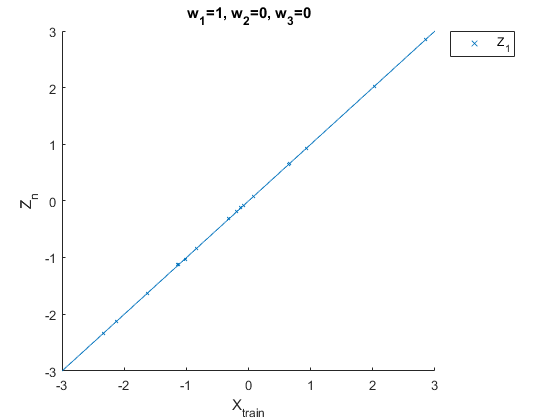

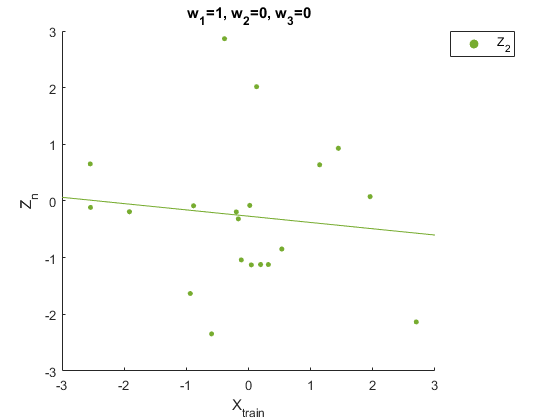

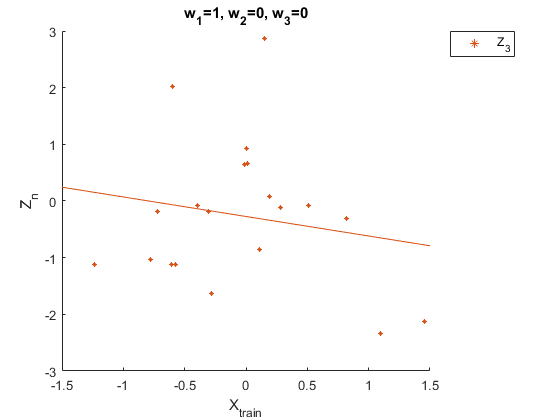

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


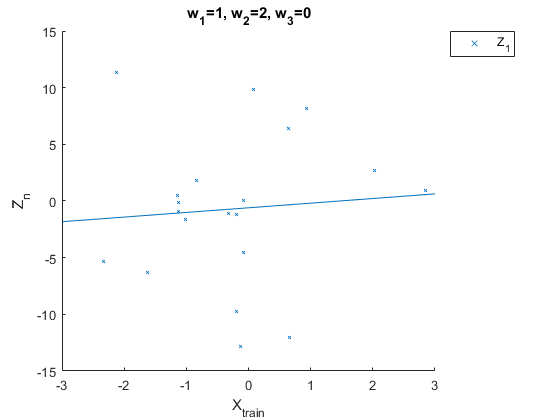

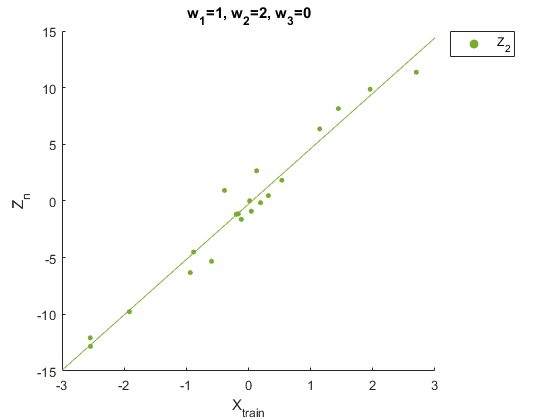

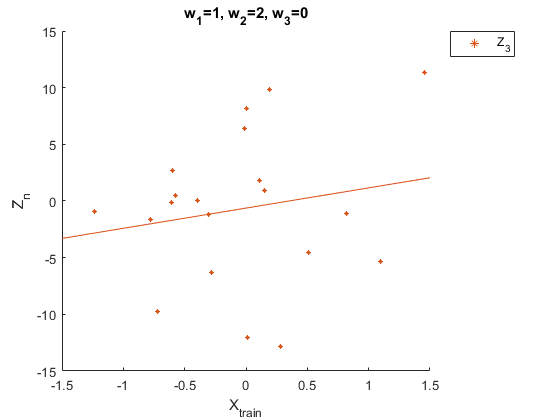

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


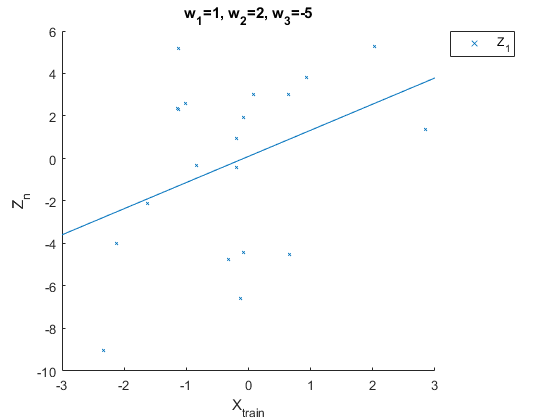

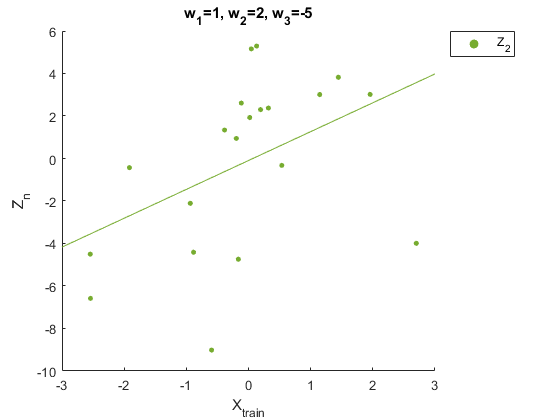

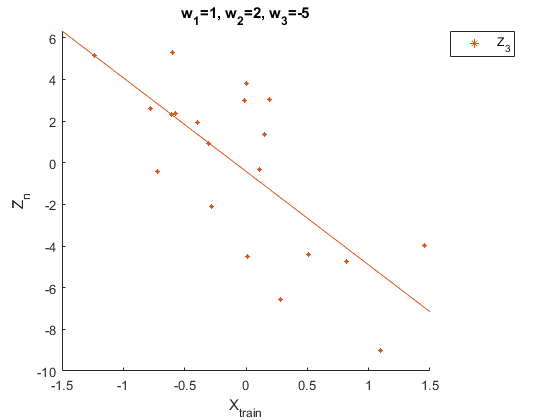

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 22
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


% !!! IMPORTANT: ADD ALL FUNCTIONS TO MATLAB PATH !!!
addpath(genpath('.'))

% Initialize inputs using random numbers using a fixed random number
% generator (rng)
rng(2);
X = normrnd(0, 1, [3, 20]);

% Example with three different w vectors
wArray = [[1; 0;  0], ...   % One activation node
          [1; 5;  0], ...   % Two activation nodes
          [1; 2; -5]];      % Three activation nodes
b = randn([1, 20]) * 0.01;

% Construct several values for Z by changing the weight
% parameters and plotting the least-square lines.
for i = 1:size(wArray, 2)
    Z1{i} = X' * wArray(:, i) + b';
    plotLSLines(X', Z1{i}, 'weights', i)
end

As you can see, each weight value highly impacts the distribution of the data in the new feature by a linear scaling factor.

#### Impact of biases on the new feature `Z` generated by the neural network 

Now that we saw how the weights scale our features linearly, let's see how the biases influence the output `Z`. To make the differences very apparent, I multiplied each bias by 100.

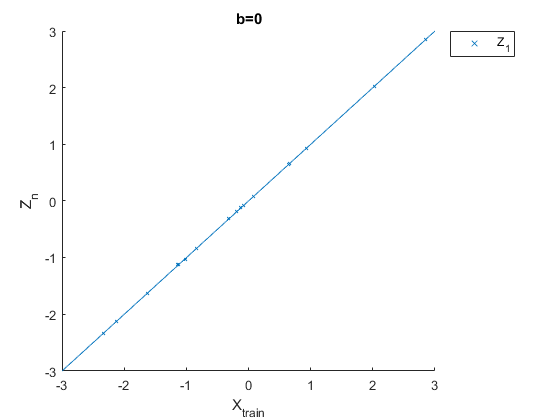

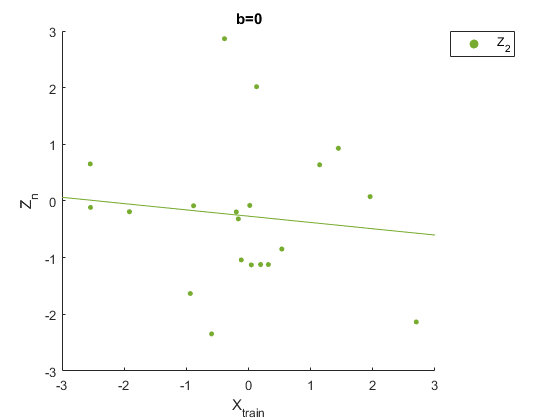

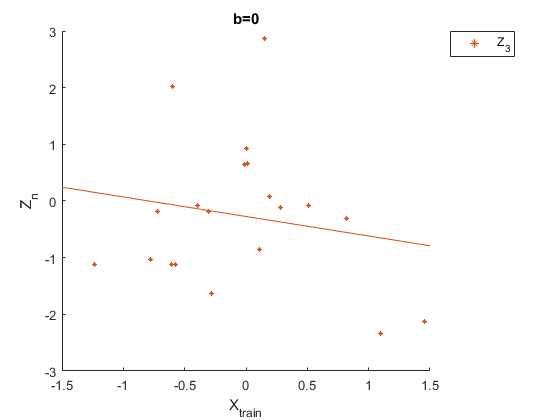

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 26
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


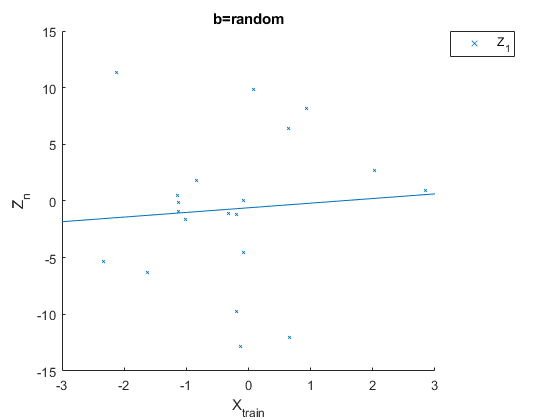

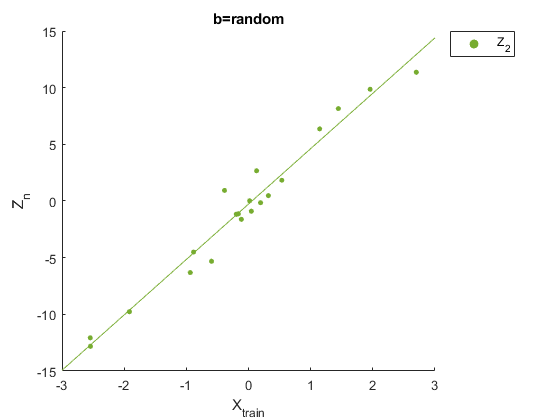

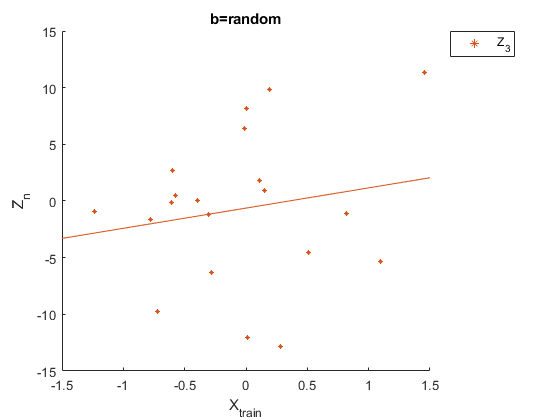

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 30
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


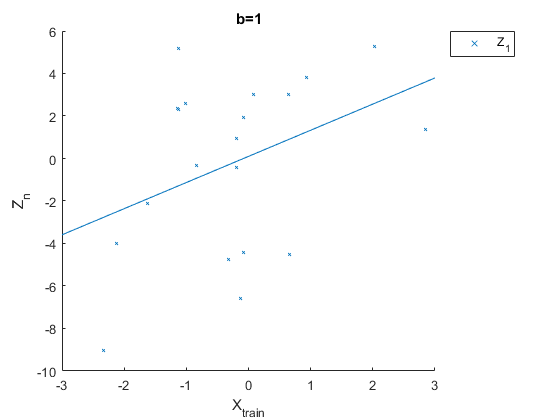

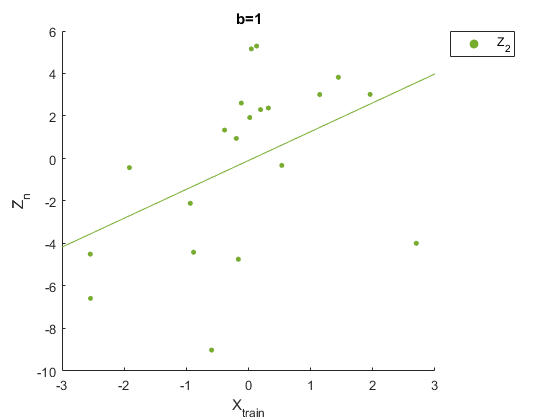

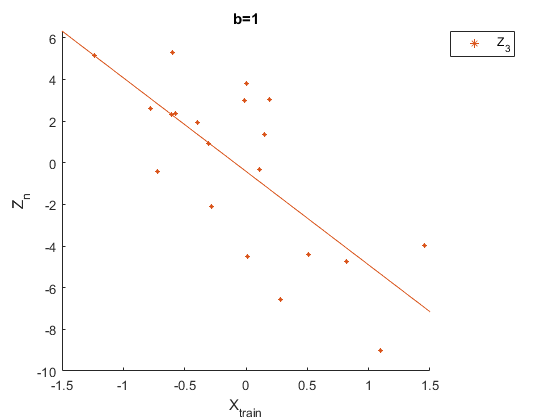

ans =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 34
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


w = [1; 2; -5];                     % Three activation nodes
bArray = [zeros([1, 20])*100; ...        % All zeros
          randn([1, 20])*100; ...        % Random values
          ones( [1, 20])*100];           % All tens

for i = 1:size(wArray, 2)
    Z2{i} = X' * w + bArray(i, :)';
    plotLSLines(X', Z1{i}, 'biases', i)
end

As you can see, each bias value highly impacts the distribution of the data in the new feature by either a linear or non-linear scale, depending on what the bias values are.

We've now covered how these two learning parameters influence the neural network, and the decisions it makes during classification. Without previous knowledge about the true nature of the data (without knowing what exactly `w` and `b` are in reality), we need to initialize these values somehow. As it turns out,[ intializing neural networks with small and random values for w and b is a better way](https://machinelearningmastery.com/why-initialize-a-neural-network-with-random-weights/) to train these parameters. We'll discuss why we need to initialize neural networks with small and random values for these parameters in later sections.  

### Non-linear transformations using an activation function

#### The sigmoid activation function

The second step involves transforming the data again using a non-linear function**. **One particular way to transform the data is to use the sigmoid activation function (aka logit transformation), where data can be transformed into a range of [0, 1]:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


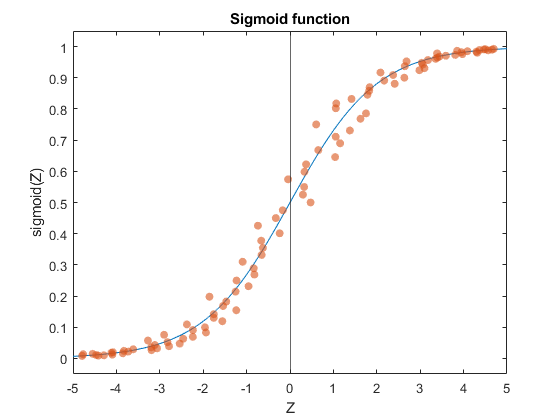

plotSigmoidFunction()

This function is especially useful for binary classification, as the logit transformation scales these values in a range of [0, 1].

We can use the `activationFnc` function provided in the project folder (documentation described below) to transform our values. Let's now transform our `Z` array using the sigmoid function and visualize the results.

**Applying the sigmoid activation function to **`Z`** values obtained from changing **`w`

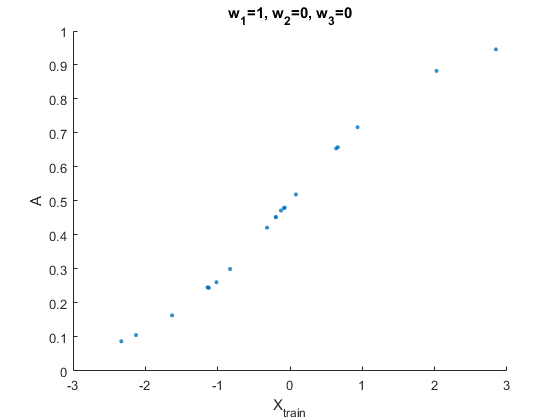

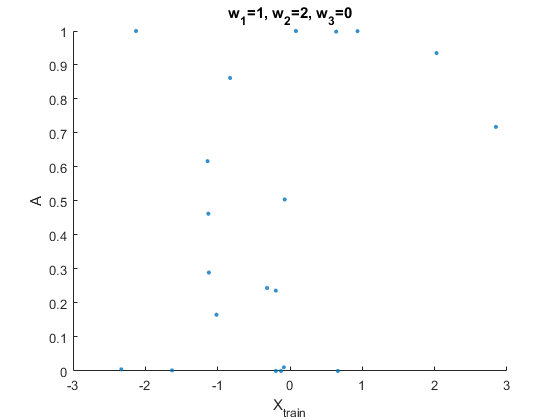

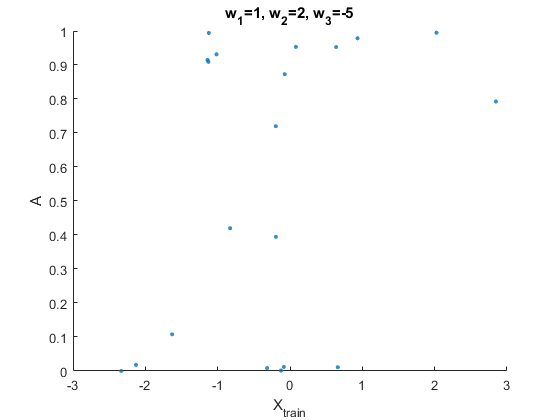

% Compute y using the Z1 cell array containing the results from using different w values
for i = 1:size(Z1, 2)
    y1{i} = activationFnc(Z1{i}', 'Sigmoid');
    plotSigmoidFunction(X', y1{i}, 'weights', i)
end

As we add more weights, the data points tends to converge to a value of 0 and 1. This is exactly how a neural network performs binary classification.

**Applying the sigmoid activation function to **`Z`** values obtained from changing **`b`

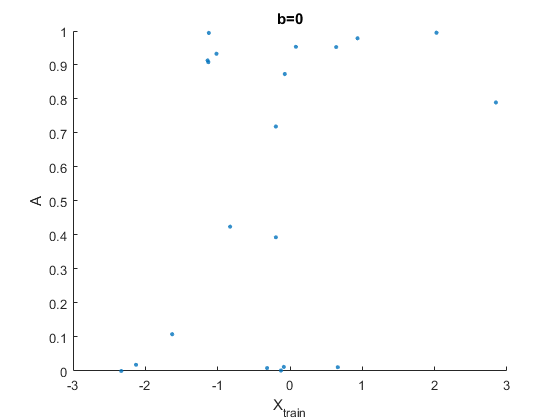

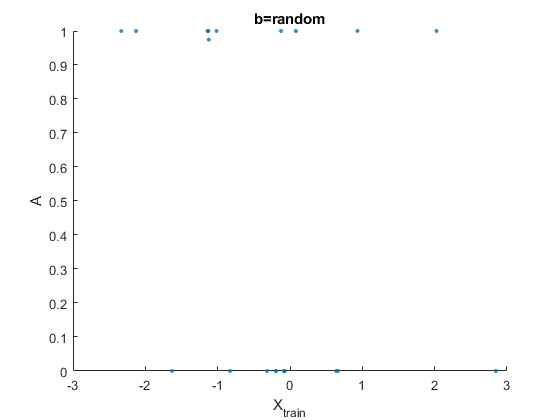

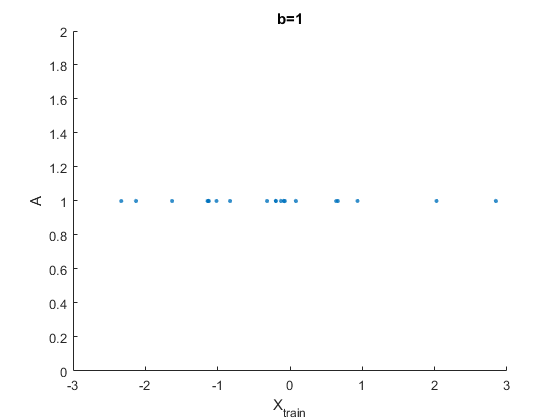

% Compute y using the Z2 cell array containing the results from using different b values
for i = 1:size(Z2, 2)
    y2{i} = activationFnc(Z2{i}', 'Sigmoid');
    plotSigmoidFunction(X', y2{i}, 'biases', i)
end

Likewise with the weights, the data points tends to converge to a value of 0 and 1 when different biases are imposed on the feature `Z`. 

Note that setting the `b=0` results in more unclassified data points, while random assignments have all values converge between either 0 or 1. It seems that randomness is helping us come to decisions faster in this particular case.

This non-linear mapping from our combined feature $Z$ to our output y shows how neural networks work at a fundamental level to come up with a decision boundary.

### Rectified linear units (ReLUs) as a preferred activation function

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. In back propagation (covered in later sections), the gradient derived from gradient descent becomes really small, resulting in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to learning model parameters.

- Further, our values are between 0 and 1. Because the values are not zero-centered, our algorithm becomes more difficult to optimize.

Thus, the formulation of the **ReLU** is as follows:


$$\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
0 & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


And the function has the following distribution:

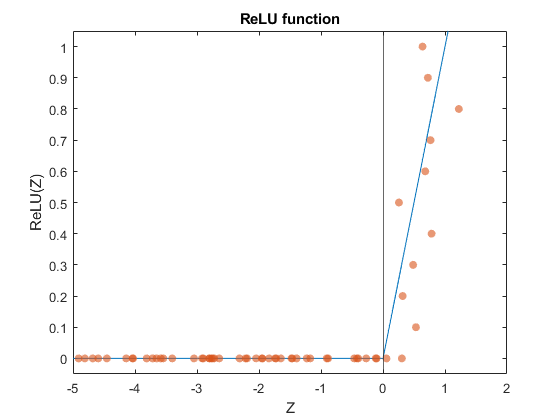

plotReLU()

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- All of the negative values have a derivative value of 0, while for positive values, the derivative is 1. Thus, this rectifies the vanishing gradient problem.

- It is also computationally economical, and easy to optimize.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

The ReLU does have its own set of problems, such as handling real negative values (since they're set to 0, the model will essentially ignore these values). 

There is an improved method of the ReLU: the** leaky ReLU**! Instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus improves our performance with negative numbers.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution:

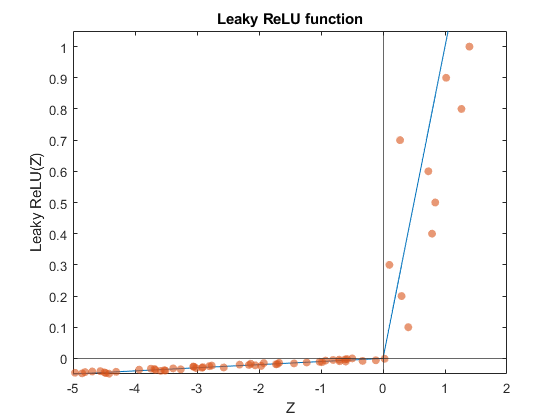

plotLeakyReLU()

To implement these different activation functions using MATLAB, we can use the `activationFnc` function. The docstring is provided below:

There are [several other potential activation functions](https://ml-cheatsheet.readthedocs.io/en/latest/activation_functions.html) that can be applied to different problems, but for simplicity, we have only encoded these three in the `activationFnc` script. 

Now that we have covered a single round of both linear and non-linear transformations, we have the tools to run a full round of forward propagation. 

### A full round of forward propagation

Let's now put all of these concepts together to run forward propagation in a shallow neural network using a breast cancer datasets built into MATLAB. 

The dataset can be called using the `load cancer_dataset function`, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. A brief description of the dataset: 

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first column corresponds to benign, and the the second column corresponds to malignant. Thus, we will perform binary classification.

To save space in the code blocks in this lecture, an accessory function `loadCancerData` has been made to:

- Load the dataset and target variables

- Split the dataset and target variables into training and test datasets

- Standardize the input datasets to have a mean = 0 and standard deviation of 1. 

We'll use only 2 activation nodes in the hidden layer.** Our hypothesis is that two activation nodes are able to capture the differences in a 2-class (binary) classification problem. **We'll discuss an empirical way to evaluate the number of hidden nodes needed in an optimal neural network in the next lecture.

The ReLU activation function will be used to demonstrate the implementation of forward propagation. However, you can feel free to test out the other activation functions, and how they impact the output from the model. 

clear all;
rng(2);

[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

w1 = randn([size(Xtrain, 2), 2]) * 0.01;
b1 = randn([size(Xtrain, 1), 1]) * 0.01;

Let's now run forward propagation, first from the input layer to the hidden layer:

actFnc = 'ReLU';
Z1     = Xtrain * w1 + b1;
A1     = activationFnc(Z1, actFnc);

Now we need to run forward propagation one more time, from the hidden layer to the output layer. We will use the values `A1` as the input for this round. Additionally, we will not bias our answers in this layer.

w2 = rand(2, 1) * 0.01;

Z2 = A1 * w2;
A2 = activationFnc(Z2, actFnc);
ypred = A2;

That's one full round of forward propagation! Now we need to now see how well our model performed using a cost function.

## Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a binary classification problem, we can use the **Cross-Entropy cost function.**

### **Cross-Entropy cost function**

Recall the formulation for the Cross-Entropy cost function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-y^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where $m$ = number of observations, $y_{\textrm{train}}$ = the response variable, and $y_{\textrm{pred}}$ = the predicted value for$y_{\textrm{train}}$ from forward propagation. The **cost** value can be computed using the `costFunction` function provided. The docstring is provided below:

J = costFunction(Ytrain, ypred, 'Log-Loss');

Now that we have a cost value, we can start to optimize our neural network algorithm using backward propagation.

## Optimizing neural network parameters using backward propagation

After computing the cost, we need to optimize the model parameters (`w` and `b)` until the error is either below a given threshold we assign, or after a certain number of iterations. This can be done using an optimization algorithm we covered earlier in the course called **gradient descent, **where we're adjusting the model parameters by following the gradient that minimizes the model error. Specifically for neural networks, we need to **back propagate** and compute the gradients **dW** and **db** using the variables we computed in forward propagation. 

### Finding the gradients dW and db using back propagation

To propagate the loss $J$ with respect to the parameters $W$ and $b$, we need to compute the gradients `dW` and `db. `Two differential equations are used:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

We won't go over the derivation for each term, but in practice, we would work these differential equations individually, multiply them together as shown above, and carry out gradient descent for each layer and each parameter in the neural network. After working out the differential equations, we get the following set of equations that are needed to compute `dw2`, `dw1`, and `db1.`

Output layer to hidden layer: $\textrm{dZ2}=\textrm{A2}-Y_{\textrm{train}} ;\;d\textrm{W2}=\textrm{dZ2}\cdot {\textrm{A1}}^T \cdot \frac{1}{m}$; $\;\textrm{db2}=0$

Hidden layer to input layer: $\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right);\;d\textrm{W1}=\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \cdot \frac{1}{m};\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$

The sigmoid activation function derivative term: $g^{\prime } \left(\textrm{Z1}\right)\;=\;\textrm{sigmoid}\left(\textrm{Z1}\right)\cdot \left(1-\textrm{sigmoid}\left(\textrm{Z1}\right)\right)\equiv \left(1-{\textrm{A2}}^2 \right)$

### Optimizing parameters `W` and `b` using gradient descent

Recall that the objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters **W** and **b**, we have two equations to update:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\alpha \cdot \textrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}-\left(\alpha \cdot \textrm{db}\right)
\end{array}$$
 

where $\alpha$ is the learning rate hyperparameter, a constant value that controls how fast we move along the gradient.  

### A full round of back propagation

Now let's codify the expressions above to run a full round of back propagation. First we need to initialize constants that will be used in back propgation. A good starting point for the learning rate is 0.05. 

alpha = 0.05;
m = size(Xtrain, 1);

First let's back propagate from the output layer to the hidden layer:

dZ2 = A2 - Ytrain;
dW2 = (1/m) .* (A1' * dZ2);

Next let's back propagate from the hidden layer to the input layer:

dZ1  = (w2 * dZ2') .* (1 - A1.^2)';
dW1  = (1/m) .* Xtrain' * dZ1';
db1  = (1/m) .* sum(dZ1', 2);

And finally, let's update the values using gradient descent:

w2 = w2 - (alpha .* dW2);
w1 = w1 - (alpha .* dW1);
b1 = b1 - (alpha .* db1);

We have successfully back propagated to get better values for `W` and `b. `To train the neural network even more, we would iterate the entire process of forward propagation, computing the cost, and backward propagation several times until we reach the minimum cost value. We'll do this in the next lecture.

## Summary

We have covered how neural networks work under the hood, and coded a shallow neural network from scratch. There are three general steps to training and optimizing a neural network: 1) forward propagation (linear and non-linear transformations) of the input data, 2) evaluating the cost, and 3) optimizing the learned parameters using back propagation and gradient descent. This lecture also covers three types of non-linear transformations we can impose on the dataset: the logit , rectified-linear unit, and the leaky rectified linear unit transformation. 

In the next lecture, we'll combine what we've learned in this lecture and train a shallow neural network using a breast cancer dataset. We will also cover some of the issues commonly encountered in training a neural network. Finally, we'll benchmark the neural network against a logistic regression classifier.

## Additional reading and references 

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).